Multi-Fidelity GP model

Takes a list of GPs as an input and a mean function and a kernel object

clear
clc

A = 0.5; B = 10; C = -5;
ff{1} = @(x) (6*x-2).^2.*sin(12*x-4);
ff{2} = @(x) 0.4*ff{1}(x)-x-1;
ff{3} = @(x) A*ff{1}(x)+B*(x-0.5)-C; 

xx = linspace(0,1,100)';
yy = ff{1}(xx);


x{1} = [0;0.2;0.75;1];
y{1} = ff{1}(x{1});

for i = 2:3
x{i} = [x{1};lhsdesign(10,1)];
y{i} = ff{i}(x{i});
end

ma = means.const(1);
mb = means.linear(2);%*means.sine(1,10,0,1);

a = kernels.Matern52(1,[0.2 0.1 0.3]);
b = kernels.RQ(2,1,0.3);
a.signn = eps;
b.signn = eps;

tic
for i = 1:3
    Z{i} = GP(mb,b);
    Z{i} = Z{i}|[x{i} y{i}];
    Z{i} = Z{i}.train2();
end
toc

Elapsed time is 1.074153 seconds.


tic
MF = NLMFGP(Z,ma,a);
MF = MF.condition();
MF = MF.train2();
toc

Elapsed time is 0.203423 seconds.


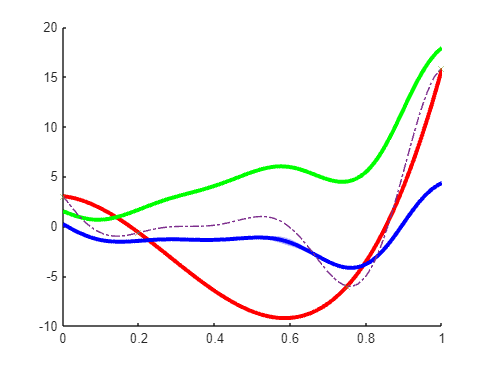

figure
hold on
utils.plotLineOut(Z{1},1,1,'color','r')
utils.plotLineOut(Z{2},1,1,'color','b')
utils.plotLineOut(Z{3},1,1,'color','g')
plot(xx,yy,'-.')
plot(x{1},y{1},'x')

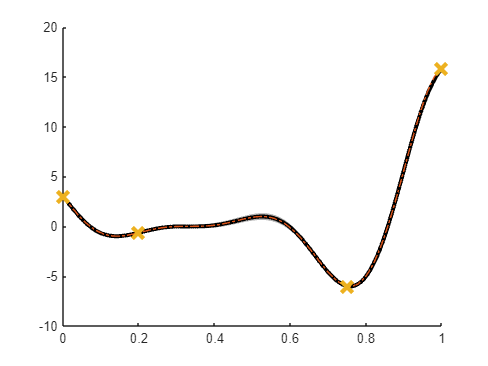

figure
hold on
utils.plotLineOut(MF,1,1)
plot(xx,yy,'-.')
plot(x{1},y{1},'x','MarkerSize',12,'LineWidth',3)

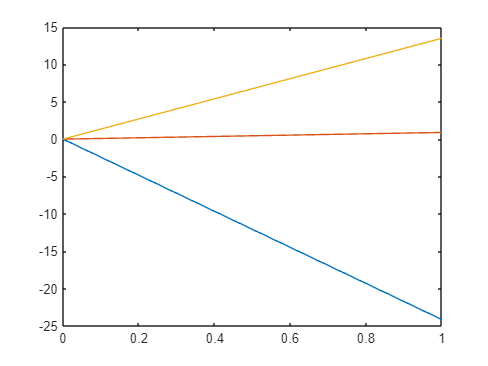

ym1 = MF.GPs{1}.mean.eval(xx);
ym2 = MF.GPs{2}.mean.eval(xx);
ym3 = MF.GPs{3}.mean.eval(xx);


figure
plot(xx,ym1)
hold on
plot(xx,ym2)
plot(xx,ym3)

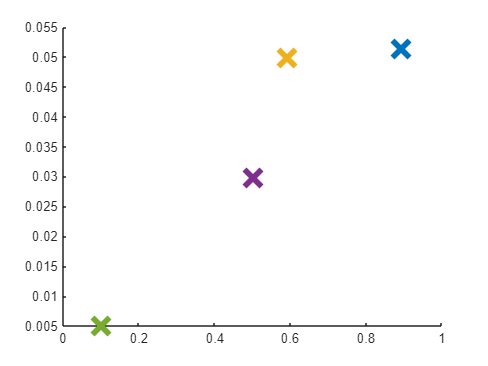

figure
hold on
tic
for i = 1:5
    [xn{i},R{i}] = BO.argmax(@BO.maxVAR,MF);
    plot(xn{i},R{i},'x','MarkerSize',18,'LineWidth',4)
end
xlim([0 1])

toc

Elapsed time is 0.969413 seconds.


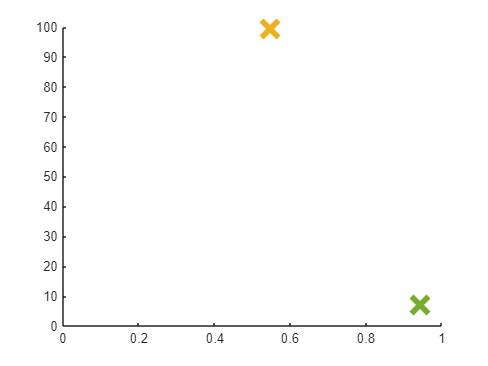

figure
hold on
tic
for i = 1:5
    [xn{i},R{i}] = BO.argmax(@BO.MFSFDelta,MF);
    plot(xn{i},R{i},'x','MarkerSize',18,'LineWidth',4)
end
xlim([0 1])

toc

Elapsed time is 2.977691 seconds.


% mc = means.linear(2);%*means.sine(1,10,0,1);
% c = kernels.Matern52(1,0.3);
% c.signn = eps;
% 
% %LOOZ = GP(mc,c);
% LOOZ = LOOZ|[x{1} MF.LOO];
% LOOZ = LOOZ.train();
% 
% figure
% hold on
% 
% tic
% for i = 1:3
%     [xn{i},R{i}] = BO.argmax(@BO.UCBSig,LOOZ);
%     plot(xn{i},R{i},'x','MarkerSize',18,'LineWidth',4)
% end
% xlim([0 1])
% toc
% 
% utils.plotLineOut(LOOZ,1,1,'color','k')
